# Example 2.2

% Jonghwan Lee, Feb 2021

## Constants and given values

clear;

c = 3e8;  % speed of light (m/s)

E0 = 2.0;  % amplitude
nu = 1e8;  % frequency
omega = 2*pi*nu;  % angular frequency
k_hat = [2 1 0] / norm([2 1 0]);  % unit vector of k

k = omega/c*k_hat  % k vector

k =     1.8733    0.9366         0


## Make a 2D grid of (x,y).

dx = 0.1;  % sampling interval [m]
x = -10:dx:10;
y = -5:dx:5;  % set dy = dx
[gx,gy] = ndgrid(x,y);
size(gx)  % check the size

ans =    201   101


gx

gx =   -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000
   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -

gy

gy =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000
   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -

## Obtain and plot a 2D array of E field magnituide at each time point to make a video.

Make a 1D array of time.

tMax = 20e-9;  % the maximum time until which we will make a video
dt = 0.1e-9;  % time step for each frame in the video
t = 0:dt:tMax;  % an array of time points
nt = length(t);
t

t = 	1.0e+-7 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Make the video.

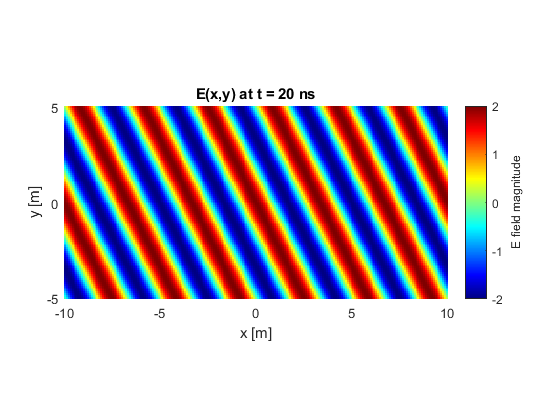

v = VideoWriter('ex2.mp4','MPEG-4');  % the result video will be saved as ex6.mp4
v.Quality = 95;
v.FrameRate = 10;  % 10 frames per second.  Each frame is 0.1 ns, thus 1 ns video per second (i.e., 200 frames or 20 s in total)
open(v);

figure;  colormap(jet);
hold on;  
for it=1:nt
    t1 = t(it);
    
    % repeat the code of Ex 2.1 for the given point t1
    E = E0 * cos(k(1)*gx + k(2)*gy + k(3)*0 - omega*t1);  % z = 0 on the xy plane, t = t1
    imagesc(x,y,E');  % use the transpose because imagesc() plots the first dimension of the 2D array (x here) in the vertical axis
    axis image;  % make x and y scale identical
    set(gca,'ydir','normal');  % without this, imagesc() has the vertical axis start from the top
    set(gca,'clim',[-2 2]);  % we know the E field magnitude should be between -2 and 2.
    cb = colorbar;
    cb.Label.String = 'E field magnitude';
%     cb.Label.Rotation = 270;  cb.Label.Position(1) = 3;
    xlabel('x [m]');
    ylabel('y [m]');
    title(['E(x,y) at t = ' num2str(t1*1e9) ' ns']);    

    frm = getframe(gcf);
    writeVideo(v,frm);
end


close(v);